# In-Class Exercises:  Adaptive Coding and Modulation

These are some of the in-class exercises for the unit on adaptive coding and modulation.

## Problem 1:   Simple HARQ Simulation

Write MATLAB code to simulate the following simple HARQ process:

- The gNB transmits `ntbs` transport blocks (TBs) in slots `t=1,...,nslot`

- In slot `t, `the gNB uses a HARQ process with index `iharq = mod(t-1,nharq)+1=1,...,nharq`.

- If there was no previous transmission on that HARQ process or the previous transmission has been successfully transmitted, the gNB start transmitting the TB with the lowest index that has not previous started transmission.

- Each TB transmission fails with a probability `pfail`.

- If it fails, the TB will be retransmitted in the next slot for that HARQ process (i.e., `nharq` slots later)

- If it passes, assume it arrives at the UE a time `t+dly`.

Simulate this system with the parameters below.  For each `t` compute `numRx(t)`= the maximum `k` such that the first `k` TBs have been received by time `t`.  Plot `numRx(t)` vs. `t`.

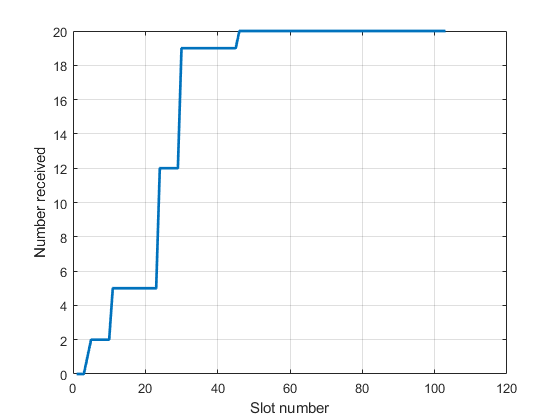

nharq = 5;
ntbs = 20;
nslot = 100;
pfail = 0.5;
dly = 3;

% Data for each TB
TBStarted = zeros(ntbs,1);   % Indicates if the TB has been started
TBRxed = zeros(ntbs,1);      % Indicates if the TB has been received
TBRxTime = zeros(ntbs,1);    % Time at which the TB has been received

% Data for each HARQ process
harqTx = zeros(nharq,1);          % harqTx(i)=1 if there is a transmission on the HARQ process
harqTBId = zeros(nharq,1);        % ID of the TB that is being transmitted on the HARQ process
harqRetxNeeded = zeros(nharq,1);  % Indicates if the last TX was successful

% Pass
pass = zeros(nslot,1);
numRx = zeros(nslot+dly,1);


for t = 1:nslot
    
    % Get the HARQ process ID
    iharq = mod(t-1, nharq)+1;
           
    if ~harqRetxNeeded(iharq)
        % If there is no retransmission, find the lowest 
        % TB ID that has not started tranmissions        
        [m,itb] = min(TBStarted);
        
        % If there are still TBs outstanding, mark the HARQ process 
        % to indicate that the transmission has started
        if m == 0
            harqTBId(iharq) = itb;
            harqTx(iharq) = 1;
            TBStarted(itb) = 1;
        end
    end     
    
    % Check if there is a TX in the HARQ process
    if harqTx(iharq)
        itb = harqTBId(iharq);
        
        pass(t) = (rand(1) > pfail);
        
        if pass(t)
            % If TB passes, mark the RX time and indicate
            % that the HARQ Re-Tx is needed
            TBRxTime(itb) = t+dly;
            TBRxed(itb) = 1;
            harqRetxNeeded(iharq) = 0;
        else
            harqRetxNeeded(iharq) = 1;
        end
    end
    
    % Find the ID k
    if all(TBRxed)
        numRx(t+dly) = ntbs;
    elseif all(TBRxed==0)
        numRx(t+dly) = 0;
    else
        [~,im] = min(TBRxed);
        numRx(t+dly) = im-1;
    end
           
    
end

% Plot results
plot(numRx,'Linewidth', 2);
xlabel('Slot number');
ylabel('Number received');
grid on;